%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms u

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,u);

%you will see that the unit tangent vector is a
%bit difficult to read and the algebra doesn't seem to be simplified
%(note I use the norm function, not abs)
T_hat_ugly=dr./norm(dr);

% we want to add some assumptions so that the algebra simplifies the way it
% should
assume(u,'real') % parameter u should be real

%now we can use the simplify function to make things look nice
T_hat=simplify(T_hat_ugly);

%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat);

%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat);

%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa);

%How about the Torsion?
tau=-dot(N_hat,(diff(B_hat,u)/norm(dr)));

21.1

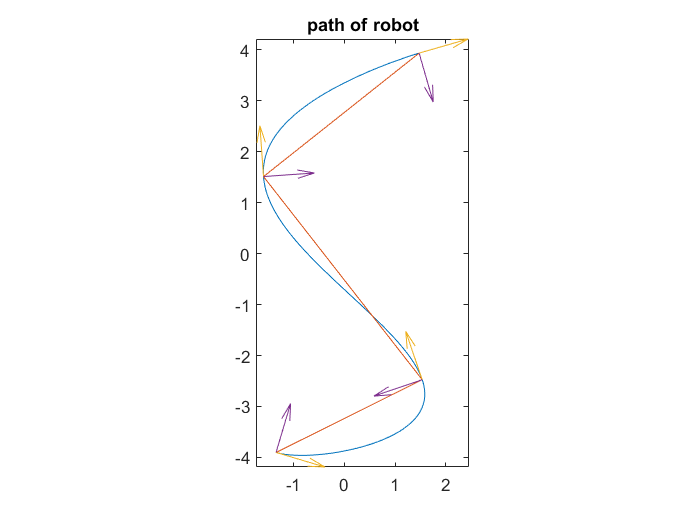

% Plot parametric curve
u_points = linspace(0,3.2,4);
T_hat_values = subs(T_hat',u,u_points);
N_hat_values = subs(N_hat',u,u_points);
xy_points = subs(r',u,u_points);

clf
fplot(ri,rj,[0,3.2])
axis equal
hold on
title("path of robot")
plot((xy_points(1,:))',(xy_points(2,:)'))
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
quiver(xy_points(1,:)',xy_points(2,:)',N_hat_values(1,:)',N_hat_values(2,:)', 0);

21.2

syms t
rt = subs(r, u, t/3)

$$rt = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,t}{60}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

linear_speed = norm(diff(rt, t))

$$linear\_speed = \sqrt{\frac{3059001\,{\left|\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{1089\,{\left|\cos\left(\frac{t}{3}+\frac{7}{5}\right)\right|}^{2}}{625}}$$

T_hat_t = diff(rt, t)/norm(diff(rt, t));
dTdt = diff(T_hat_t, t);
angular_velocity = cross(T_hat_t, dTdt)

$$angular\_velocity = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{33\,\sigma_{5}\,\left(\frac{30899\,\sigma_{3}}{25000\,\sqrt{\sigma_{2}}}+\frac{1749\,\sigma_{4}\,\sigma_{1}}{2500\,{\sigma_{2}}^{3/2}}\right)}{25\,\sqrt{\sigma_{2}}}-\frac{1749\,\sigma_{4}\,\left(\frac{11\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)}{25\,\sqrt{\sigma_{2}}}-\frac{33\,\sigma_{5}\,\sigma_{1}}{50\,{\sigma_{2}}^{3/2}}\right)}{1250\,\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{726\,\mathrm{sign}\left(\sigma_{5}\right)\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)\,\left|\sigma_{5}\right|}{625}-\frac{54042351\,\left|\sigma_{4}\right|\,\mathrm{sign}\left(\sigma_{4}\right)\,\sigma_{3}}{15625000}\\ \sigma_{2}=\frac{3059001\,{\left|\sigma_{4}\right|}^{2}}{1562500}+\frac{1089\,{\left|\sigma_{5}\right|}^{2}}{625}\\ \sigma_{3}=\cos\left(\frac{53\,t}{60}+\frac{371}{100}\right)\\ \sigma_{4}=\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)\\ \sigma_{5}=\cos\left(\frac{t}{3}+\frac{7}{5}\right) \end{array}$$

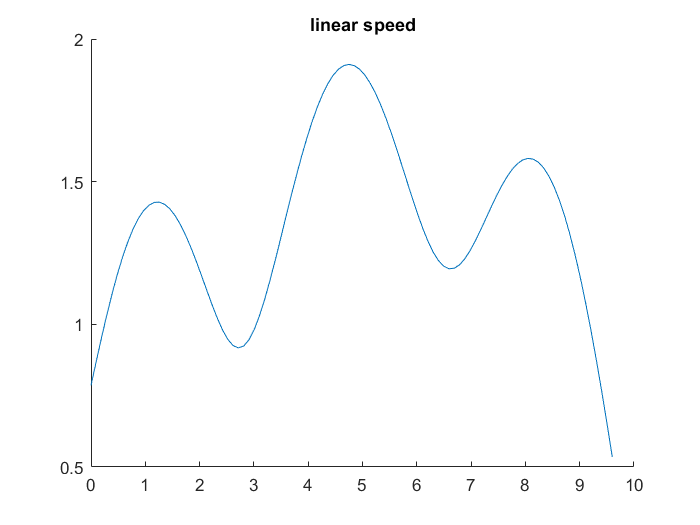


t_points = linspace(0,3.2*3, 100);

linear_speed_points = subs(linear_speed, t, t_points);
angular_velocity_points = subs(angular_velocity', t, t_points);
clf
hold on
plot(t_points, linear_speed_points')
title("linear speed")
hold off

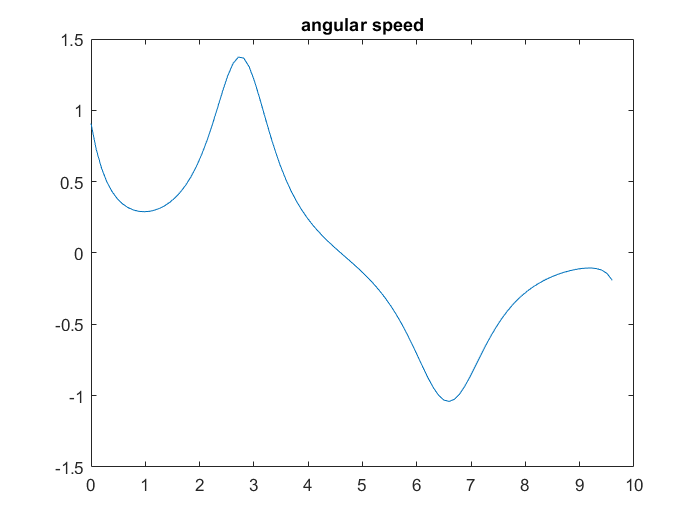


clf
plot(t_points, angular_velocity_points(3,:)')
title("angular speed")

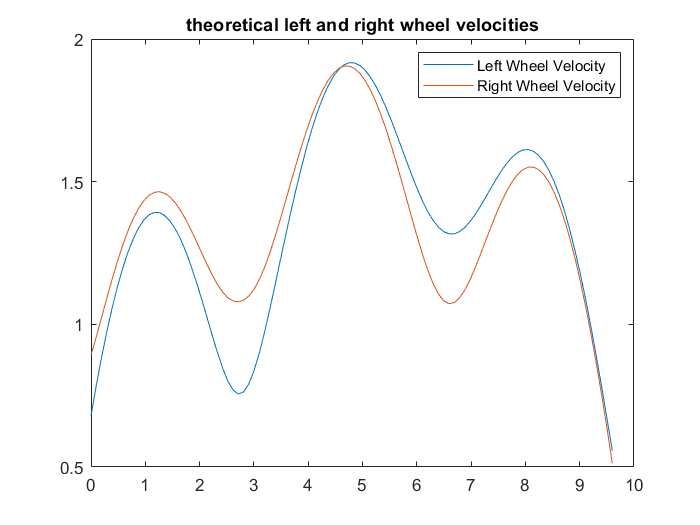

wheelbase = 0.235; %Meters
left_wheel_velocity = linear_speed - angular_velocity(:,3)*wheelbase/2;
right_wheel_velocity = linear_speed + angular_velocity(:,3)*wheelbase/2;
left_velocity_points = subs(left_wheel_velocity',t,t_points);
right_velocity_points = subs(right_wheel_velocity',t,t_points);
plot(t_points,left_velocity_points)
title("theoretical left and right wheel velocities")
hold on
plot(t_points,right_velocity_points)
hold off
legend('Left Wheel Velocity','Right Wheel Velocity')

encoderRightmeters = encoderRightmeters - encoderRightmeters(1);

encoderRightmeters =          0
    0.0385
    0.0769
    0.1154
    0.1538
    0.1923
    0.2307
    0.2692
    0.3076
    0.3461


encoderLeftmeters = encoderLeftmeters - encoderLeftmeters(1);

encoderLeftmeters =          0
    0.0418
    0.0836
    0.1254
    0.1672
    0.2091
    0.2509
    0.2927
    0.3345
    0.3763


timeseconds =          0
    0.1020
    0.2000
    0.3010
    0.4010
    0.5020
    0.5990
    0.7010
    0.8000
    0.9020


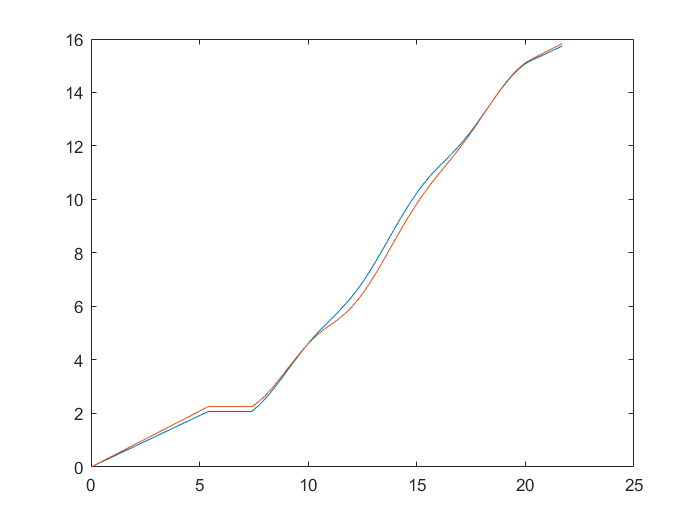

timeseconds = timeseconds - timeseconds(1);

encoderRightmeters = encoderRightmeters(76:200);
encoderLeftmeters = encoderLeftmeters(76:200);
timeseconds = timeseconds(76:200);

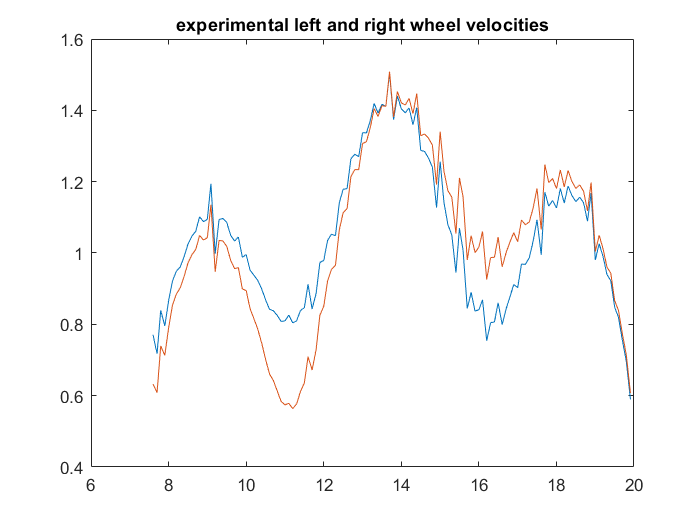

clf
velocity_R = diff(encoderRightmeters) ./ diff(timeseconds);
velocity_L = diff(encoderLeftmeters) ./ diff(timeseconds);
plot(timeseconds(2:end), velocity_R)
hold on
plot(timeseconds(2:end), velocity_L)
title("experimental left and right wheel velocities")
hold off

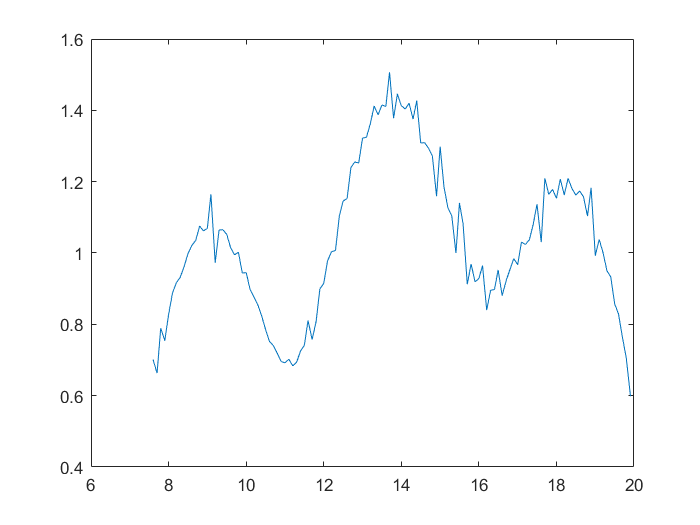

clf
linear_experiment_speed = (velocity_L + velocity_R) / 2;

plot(timeseconds(2:end), linear_experiment_speed)

title("linear experimental speed")

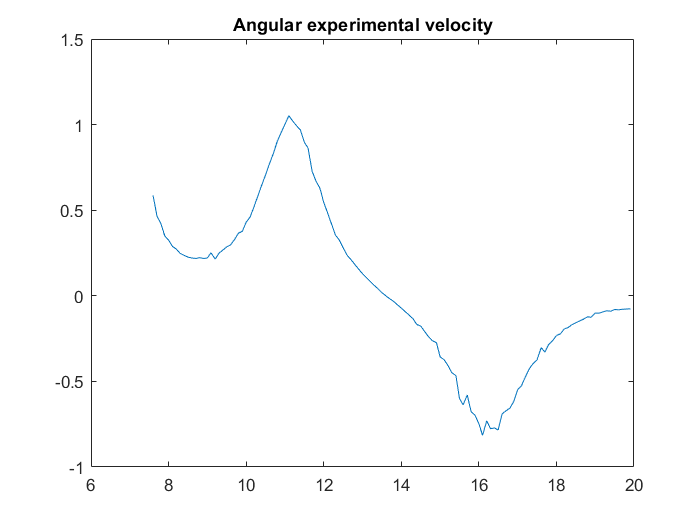

angular_experiment_speed = (velocity_R - velocity_L) / wheelbase;
clf
plot(timeseconds(2:end), angular_experiment_speed)
title("Angular experimental velocity")

starting_T_hat = double(subs(T_hat, u, 0));
starting_theta = atan(starting_T_hat(2)/starting_T_hat(1));
starting_position = double(subs(r(1:2), u, 0));
theta_experimental = [starting_theta];
position_experimental = [starting_position];

for i = 1:length(angular_experiment_speed)
    delta_t = diff(timeseconds);
    next_angle = theta_experimental(i) + (angular_experiment_speed(i))*(delta_t(i));
    theta_experimental = [theta_experimental; next_angle];
end
for i = 1:length(linear_experiment_speed)
    delta_t = diff(timeseconds);
    experimental_T_hat = [cos(theta_experimental(i)), sin(theta_experimental(i))];
    change = linear_experiment_speed(i).*experimental_T_hat*delta_t(i)
    next_position = position_experimental(i,:) + change;
    position_experimental = [position_experimental; next_position];
end

change =     0.0625   -0.0186


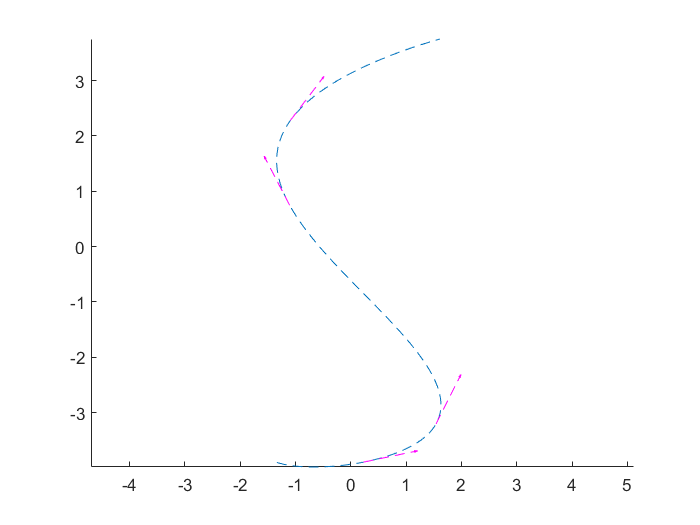

clf
hold on
plot(position_experimental(:,1), position_experimental(:,2),'--')
axis equal


quiver(position_experimental(18,1),position_experimental(18,2), cos(theta_experimental(18)), sin(theta_experimental(18)), 0, 'm--')
quiver(position_experimental(35,1),position_experimental(35,2), cos(theta_experimental(35)), sin(theta_experimental(35)),0, 'm--')
quiver(position_experimental(78,1),position_experimental(78,2), cos(theta_experimental(78)), sin(theta_experimental(78)),0, 'm--')
quiver(position_experimental(95,1),position_experimental(95,2), cos(theta_experimental(95)), sin(theta_experimental(95)),0, 'm--')